clc; clear; close all;

RBE 501 – Robot Dynamics Fall 2022

Sean Berta

Final Exam

Assigned: 12/5/2022

Due: 12/11/2022 by 11:59PM

This exam applies the principles learned during the first and second half of the semester to the dynamic 

modeling of two manipulators. Questions 1-4 apply to the SCARA arm of figure 1.  Question 5 and 6 apply 

to the 2DOF RP manipulator shown in figure 2. Upload a PDF of your answers and show your work. You 

are allowed (and likely need) to use Matlab to solve the problems, you will also upload your Matlab code. 

Questions 1-5 are worth 4 points each and question 6 is worth 5 points. 

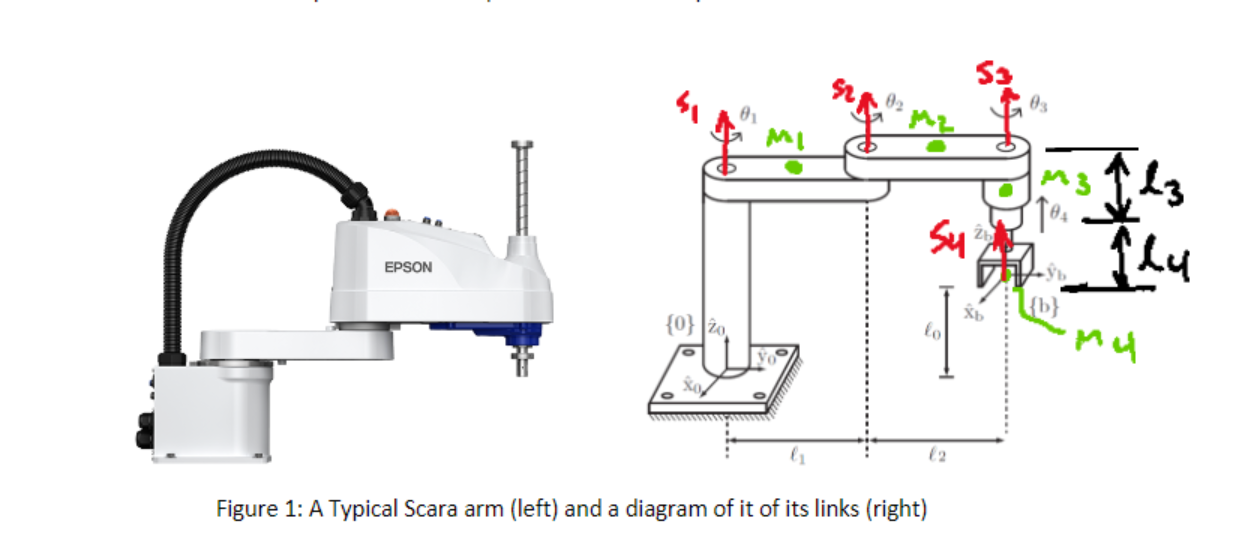

Figure 1: A Typical Scara arm (left) and a diagram of it of its links (right)

The center of mass of links 1, 2, and 3 are located halfway along their length. The center of mass of link 

4 is located at the center of the gripper (i.e. at the body frame). Model links 1 and 2 as rectangular 

parallelepipeds with the dimensions shown above. Model links 3 and 4 as point masses. Consider the 

center of Links 1 and 2 to be at the same z coordinate equal to L0+L3+L4. 

**(4pts) Question 1 Newton Euler Dynamics - Robot Description: **

Consider the configuration shown in figure 1 to be the home configuration of the robot, write the 4X4 

home configuration matrix of the body frame, 𝑀, and for the center of mass of each link, 

𝑀1, 𝑀2, 𝑀3, 𝑎𝑛𝑑 𝑀4. Fill out the table listed below for the screw axes in the space frame. Write the 

spatial inertia matrix of each link 𝐺1, 𝐺2, 𝐺3, 𝑎𝑛𝑑 𝐺4. 

𝒊 𝝎𝒊 𝒗𝒊

1

2

3

4

𝑀 = [ ]

𝑀1 = [ ]               𝑀2 = [ ]

𝑀3 = [ ]                𝑀4 = [ ]

𝐺1 = [ ]               𝐺2 = [ ]

𝐺3 = [ ]                𝐺4 = [ ]

Step 1) Defining the screw axes and the robot.

syms(sym('theta',[1 6], 'real'));
syms Mas_M(theta) C(theta,thetad) gr(theta) q1(t) q2(t) L1 L2 m1 m2 g 
syms(sym('L',[1 5], 'real'));
syms L0
L = [.5 0.3 0.3 0.1 0.1];
m = [1.5 1.5 0.5 0.5];

% v_num = subs(v,[L1, L2, L3, L4, L5],L);
% M_num = subs(M,[L1, L2, L3, L4, L5],L);
numJoints = 4 ;
W = sym('W',[numJoints 3]);
q = sym('q',[numJoints 3]);
W(1,:) = [0 0 1];
W(2,:) = [0 0 1];
W(3,:) = [0 0 1];
W(4,:) = [0 0 0];

q(1,:) = [0 0 L0+L3+L4];
q(2,:) = [0 L1 L0+L3+L4];
q(3,:) = [0 L1+L2 L0+L4];
q(4,:) = [0 L1+L2 L0];

v = sym('v',[numJoints 3]);
for idx = 1:numJoints 
    v(idx,:) = -cross(W(idx,:),q(idx,:));
end
v(4,:) = [0 0 1];

The screw axes will be:

table(W,v)

ans = 4×2 table
         W                 v        
    ___________    _________________

    0    0    1    0          0    0
    0    0    1    L1         0    0
    0    0    1    L1 + L2    0    0
    0    0    0    0          0    1


S= [W v]'

$$S = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 0\\ 0 & \bar{L_{1}} & \bar{L_{1}}+\bar{L_{2}} & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Step 2) generate the home mass and body matrix:

for this it is stated the masses are at the center of the links: with this 

M1:

M(:,:,1) = [1 0 0 0;
            0 1 0 L1/2;
            0 0 1 L0+L3+L4; 
            0 0 0 1];
M1 = M(:,:,1)

$$M1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & \frac{L_{1}}{2}\\ 0 & 0 & 1 & L_{0}+L_{3}+L_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M2

           
M(:,:,2) = [1 0 0 0;
            0 1 0 L1+L2/2;
            0 0 1 L0+L3+L4;
            0 0 0 1];
M2 = M(:,:,2)

$$M2 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & L_{1}+\frac{L_{2}}{2}\\ 0 & 0 & 1 & L_{0}+L_{3}+L_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M3

M(:,:,3) = [1 0 0 0;
            0 1 0 L1+L2;
            0 0 1 L0+L3/2+L4;
            0 0 0 1];
M3 = M(:,:,3)

$$M3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & L_{1}+L_{2}\\ 0 & 0 & 1 & L_{0}+\frac{L_{3}}{2}+L_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M4: has a varaible mass matrix due to the prismatic joint changing the position of the center of mass.

M(:,:,4) =[1 0 0 0;
0 1 0 L1+L2;
0 0 1 L0+theta4;
0 0 0 1];
M4= M(:,:,4)

$$M4 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & L_{1}+L_{2}\\ 0 & 0 & 1 & L_{0}+\theta_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M body:

M_home = [1 0 0 0;
            0 1 0 L1+L2;
            0 0 1 L0;
            0 0 0 1]

$$M\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & L_{1}+L_{2}\\ 0 & 0 & 1 & L_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% M_home = M(:,:,4)

Step 3) Solving for the spacitial interial matrix by solving the interial matrix of each of the joints

G = zeros(6,6,numJoints);

% Ii rectangularparallelepiped
l= .1;
h = .05;
w = .3;
Ii=zeros(3,3,numJoints);
for i = 1:numJoints
    
    if i > 2
        Ii(:,:,i) = zeros(3,3);
    else
        Ixx = m(i)*(w^2 + h^2)/12;
        Iyy = m(i)*(l^2 + h^2)/12;
        Izz = m(i)*(l^2 + w^2)/12;
        Ii(:,:,i) = [
            Ixx 0 0;
            0    Iyy  0;
            0     0    Izz;];
    end

end


The I matrix for the first link is:

Ii(:,:,1)

ans =     0.0116         0         0
         0    0.0016         0
         0         0    0.0125


for the second second link:

Ii(:,:,2)

ans =     0.0116         0         0
         0    0.0016         0
         0         0    0.0125


Links 3 and 4 are considered point masses and are therefore,

Ii(:,:,3)

ans =      0     0     0
     0     0     0
     0     0     0


Next solving for G:

for i = 1:numJoints
    G(:,:,i) = [Ii(:,:,i)          zeros(3,3);
      zeros(3,3)  m(i)*eye(3,3);];
end

G1:

G1 = G(:,:,1)

G1 =     0.0116         0         0         0         0         0
         0    0.0016         0         0         0         0
         0         0    0.0125         0         0         0
         0         0         0    1.5000         0         0
         0         0         0         0    1.5000         0
         0         0         0         0         0    1.5000


G2:

G2 = G(:,:,2)

G2 =     0.0116         0         0         0         0         0
         0    0.0016         0         0         0         0
         0         0    0.0125         0         0         0
         0         0         0    1.5000         0         0
         0         0         0         0    1.5000         0
         0         0         0         0         0    1.5000


G3:

G3 = G(:,:,3)

G3 =          0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0    0.5000         0         0
         0         0         0         0    0.5000         0
         0         0         0         0         0    0.5000


G4:

G4 = G(:,:,4)

G4 =          0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0    0.5000         0         0
         0         0         0         0    0.5000         0
         0         0         0         0         0    0.5000


**(4pts) Question 2 Newton Euler Dynamics - Pre-calculations: **

Calculate the screw axes of each joint in their local link frames, A1, A2, A3, and A4. Define the 

transformation matrices between adjacent links in the home configuration, M01, M12, M23, and M34 :

𝐴1 =    []    ;       𝐴2 =  []     ;       𝐴3 =  []    ;     𝐴4 =  []

𝑀01 = [ ]               𝑀12 = [ ]

𝑀23 = [ ]                𝑀34 = [ ]

Step 1) solving for the A matrices as $A_i =\textrm{ad}\left\lbrack M_i^{-1} \right\rbrack *S_i$

for i = 1:numJoints
    A(:,i) = adjoint(M(:,:,i)^-1)*S(:,i);
end


With that

A1:

A1 = A(:,1)

$$A1 = \left(\begin{array}{c} 0\\ 0\\ 1\\ -\frac{L_{1}}{2}\\ 0\\ 0 \end{array}\right)$$

A2:

A2 = A(:,2)

$$A2 = \left(\begin{array}{c} 0\\ 0\\ 1\\ \bar{L_{1}}-\frac{L_{2}}{2}-L_{1}\\ 0\\ 0 \end{array}\right)$$

A3:

A3 = A(:,3)

$$A3 = \left(\begin{array}{c} 0\\ 0\\ 1\\ \bar{L_{1}}-L_{2}-L_{1}+\bar{L_{2}}\\ 0\\ 0 \end{array}\right)$$

A4:

A4 = A(:,4)

$$A4 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 1 \end{array}\right)$$

Subing the robot parameters into them changes them to

A = subs(A,[L0,L1,L2,L3,L4],L);

A1:

A1 = A(:,1)

$$A1 = \left(\begin{array}{c} 0\\ 0\\ 1\\ -\frac{3}{20}\\ 0\\ 0 \end{array}\right)$$

A2:

A2 = A(:,2)

$$A2 = \left(\begin{array}{c} 0\\ 0\\ 1\\ -\frac{3}{20}\\ 0\\ 0 \end{array}\right)$$

A3:

A3 = A(:,3)

$$A3 = \left(\begin{array}{c} 0\\ 0\\ 1\\ 0\\ 0\\ 0 \end{array}\right)$$

A4:

A4 = A(:,4)

$$A4 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 1 \end{array}\right)$$

Step 2) Solving for the transformation matrix between adjoints where $M_{0,1} =M_i^{-1} *M_{i-1}$ since this requires M0 for the first link M0 will be and identity matrix:

M0 = eye(4,4);
for i= 1:numJoints
    if i == 1
       
        Mi(:,:,i) = M(:,:,i)^-1 * M0;
    else
        Mi(:,:,i) = M(:,:,i)^-1 * M(:,:,i-1);
    end
end

M01:

M01 = Mi(:,:,1)

$$M01 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & -\frac{L_{1}}{2}\\ 0 & 0 & 1 & -L_{0}-L_{3}-L_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M12:

M12 = Mi(:,:,2)

$$M12 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & -\frac{L_{1}}{2}-\frac{L_{2}}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M23:

M23 = Mi(:,:,3)

$$M23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & -\frac{L_{2}}{2}\\ 0 & 0 & 1 & \frac{L_{3}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M34:

M34 = Mi(:,:,4)

$$M34 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{L_{3}}{2}+L_{4}-\theta_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**(4pts) Question 3 Newton Euler Dynamics – Joint Trajectories:**

Consider the robot smoothly moving in 3 steps starting from its home position to pick up an object. 

 Step 1: Joints 1 and 2 rotate from 𝜃1 = 𝜃2 = 0 𝑟𝑎𝑑 𝑡𝑜 𝜃1 = 𝜃2 = 𝜋

2𝑟𝑎𝑑 . 

step1 ) Using a quintic polynomial the joint angles, velocities and accleration can be calulated between 2 joint configurations over 1 second.

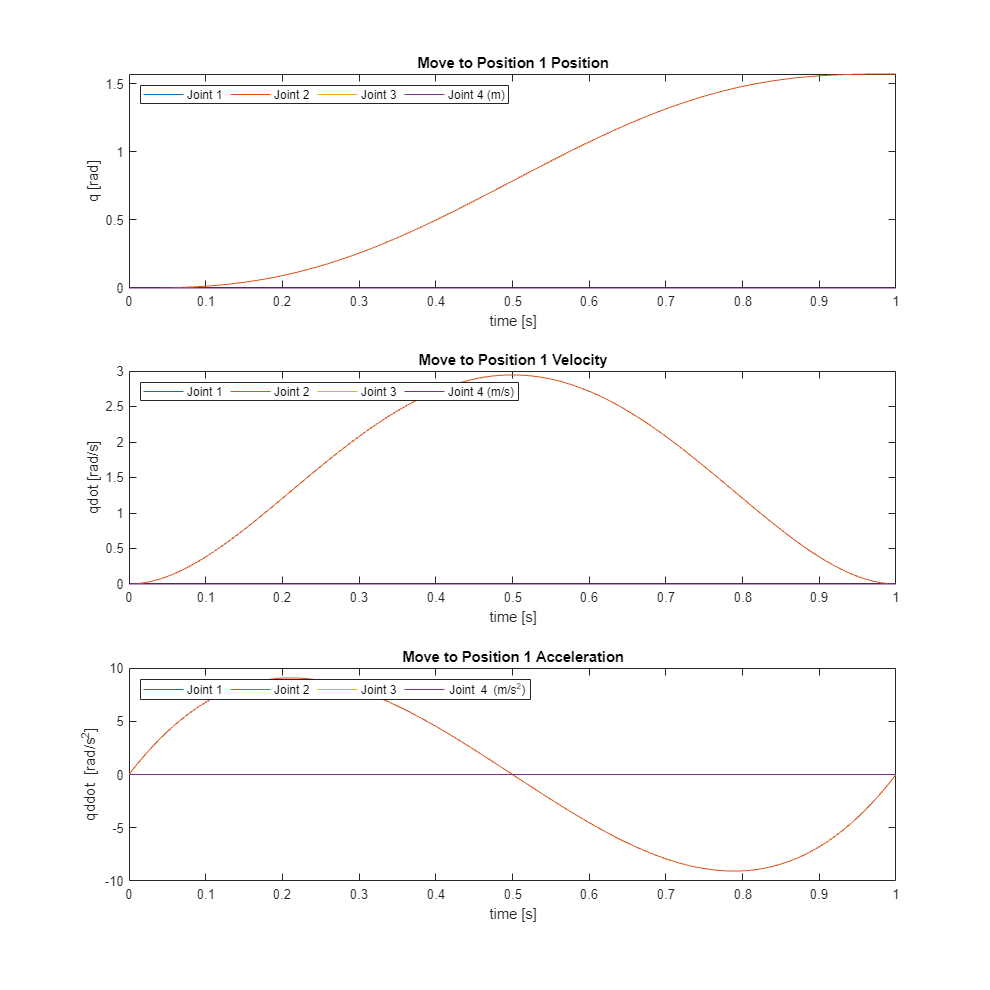

theta0 = [0 0 0 0];

theta1 = [pi/2 pi/2 0 0];
[ang_q1,vel_q1,acc_q1,t1] = pathPlanJoint(theta0,theta1,0,1);

%  Step 2: The robot drops its manipulator from 𝜃4 = 0 𝑚 𝑡𝑜 𝜃4 =   ― 0.3𝑚. 

theta2 = [pi/2 pi/2 0 -.3];
[ang_q2,vel_q2,acc_q2,t2] = pathPlanJoint(theta1,theta2,0,1);
%  Step 3: The manipulator picks up a 1kg payload and raises it from 𝜃4 = ―0.3𝑚 𝑡𝑜 𝜃4 =  0𝑚. 

theta3 = [pi/2 pi/2 0 0];
[ang_q3,vel_q3,acc_q3,t3] = pathPlanJoint(theta2,theta3,0,1);
figure("Position",[10,10,10000,10000])
plotPathFinal(ang_q1,vel_q1,acc_q1,t1,"Move to Position 1")

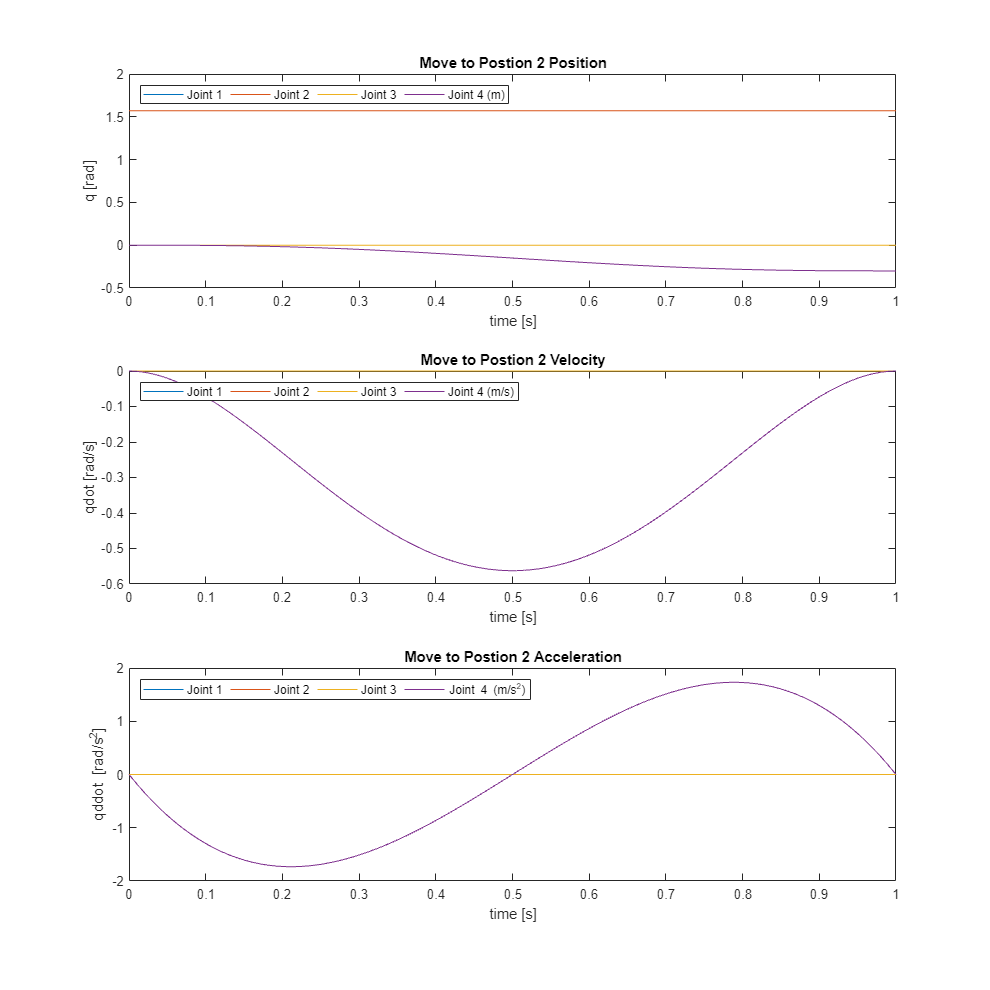

plotPathFinal(ang_q2,vel_q2,acc_q2,t2,"Move to Postion 2")

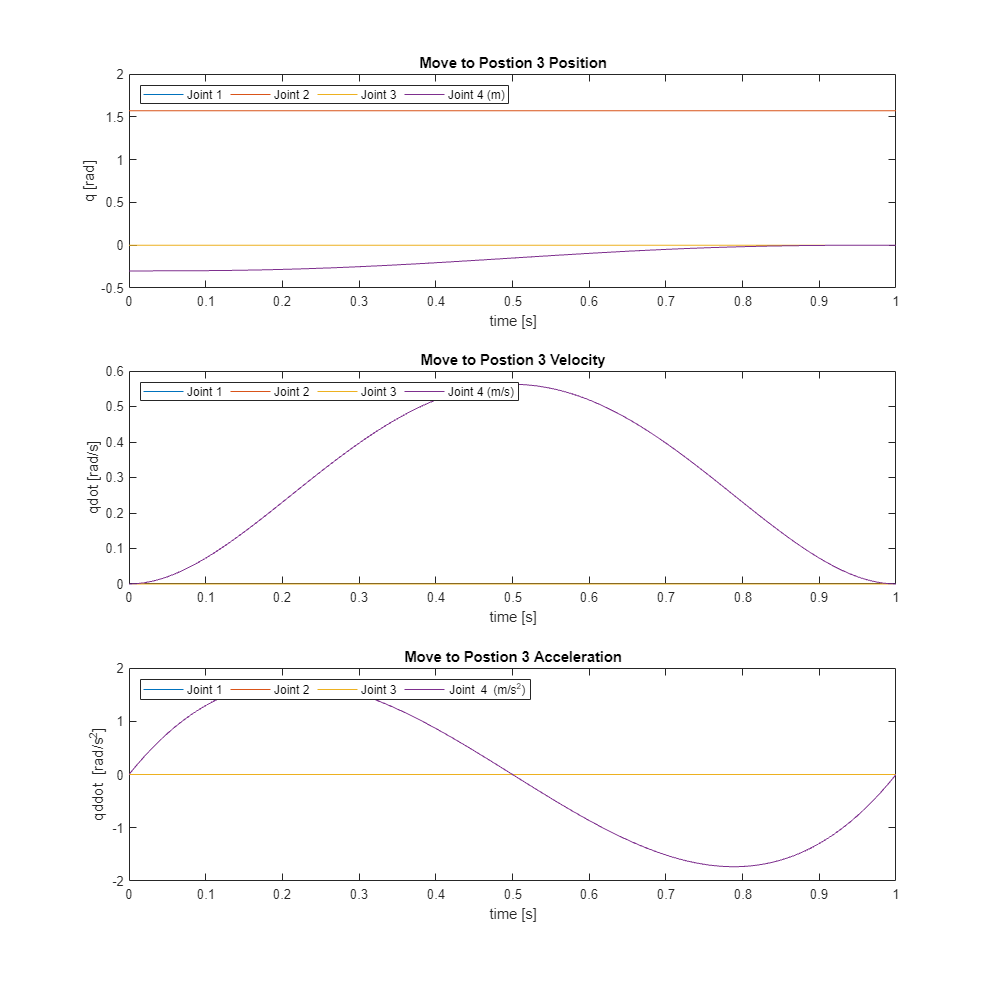

plotPathFinal(ang_q3,vel_q3,acc_q3,t3,"Move to Postion 3")

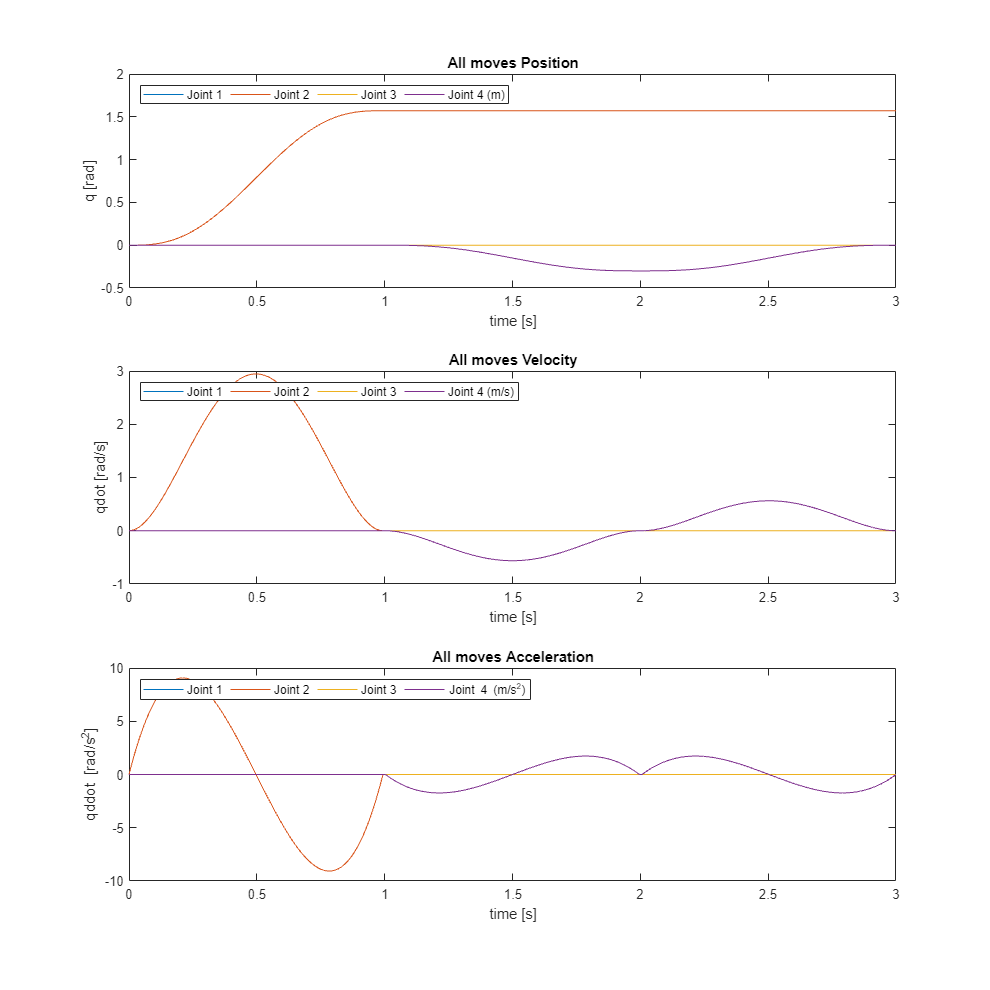



ang_qT = [ang_q1,ang_q2,ang_q3];
vel_qT = [vel_q1,vel_q2,vel_q3];
acc_qT = [acc_q1,acc_q2,acc_q3];
tt = [ t1,t2,t3];
tt = linspace(0,3,300);
plotPathFinal(ang_qT,vel_qT,acc_qT,tt,"All moves")

**(4pts) Question 4 Newton Euler Dynamics:** 

Calculate the torque of each joint through the complete movement described in question 3. Model the 

1kg payload as a point mass at body frame. Plot the torque of each joint throughout the trajectory.

step 1) Using the newton raphson method of foward and backward iteration the torques can be solved at each of the jopints while as noting that joint4 will be a force instead of a torque as it is a prismatic joint. 

tau = zeros(numJoints,1);
samples = length(t1);
tau1 = zeros(numJoints,samples);
% tool_weight =mass(7) - .5* -9.81;
Fsf= [0 0 0] ;

M = subs(M,[L0,L1,L2,L3,L4],L);
S = subs(S,[L0,L1,L2,L3,L4],L);


for x = 1:1:samples
        M = subs(M,[L0,L1,L2,L3,L4,theta4],[L,ang_q1(4,x)]);
        tau1(:,x) = motor_torque(M,S,ang_q1(:,x),vel_q1(:,x),acc_q1(:,x),m,Fsf,Ii,G,A);
       
end
tau2 = zeros(numJoints,samples);
for x = 1:1:samples
        tau2(:,x) = motor_torque(M,S,ang_q2(:,x),vel_q2(:,x),acc_q2(:,x),m,Fsf,Ii,G,A);   
end
tau3 = zeros(numJoints,samples);

On the 3rd move the robot picks up the payload and will have a 9.81 Nm payload acting downwards at the tip.

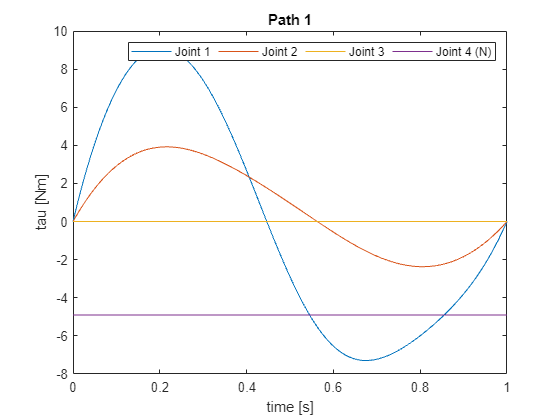

Fsf= [0 0 -9.81] ;
for x = 1:1:samples
   
        tau3(:,x) = motor_torque(M,S,ang_q3(:,x),vel_q3(:,x),acc_q3(:,x),m,Fsf,Ii,G,A);
   
    
end

figure;
plot(t1,tau1(1:4,:));
xlabel('time [s]'), ylabel('tau [Nm]'), title('Path 1');
legend({'Joint 1','Joint 2','Joint 3','Joint 4 (N)'},'Location','northeast','Orientation','horizontal')

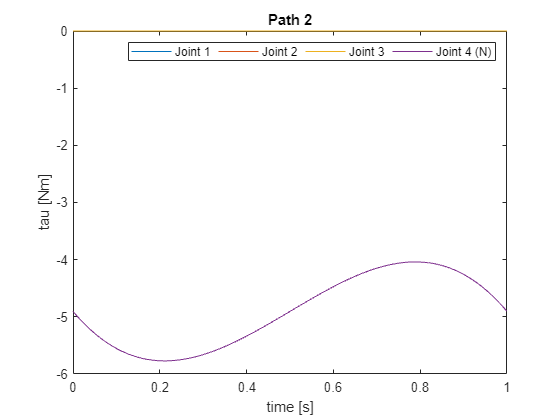


plot(t2,tau2(1:4,:));
xlabel('time [s]'), ylabel('tau [Nm]'), title('Path 2');
legend({'Joint 1','Joint 2','Joint 3','Joint 4 (N)'},'Location','northeast','Orientation','horizontal')

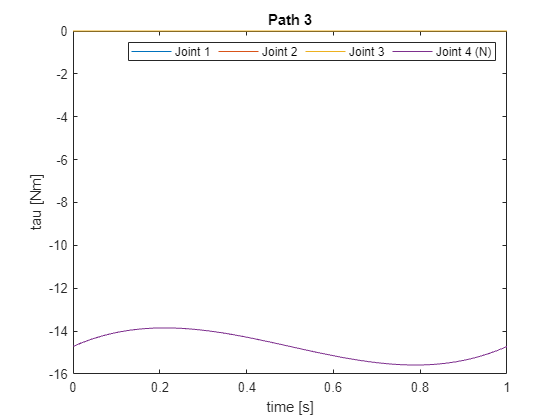


plot(t3,tau3(1:4,:));
xlabel('time [s]'), ylabel('tau [Nm]'), title('Path 3');
legend({'Joint 1','Joint 2','Joint 3','Joint 4 (N)'},'Location','northeast','Orientation','horizontal')

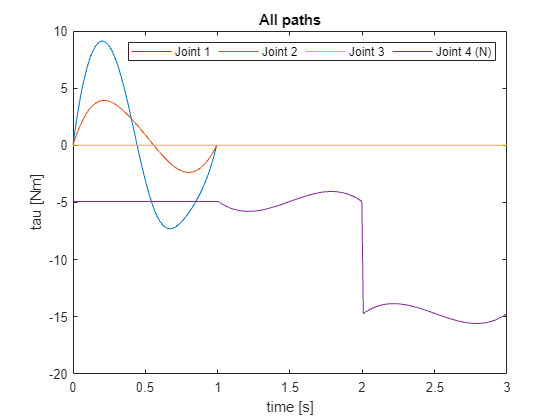


tauT = [tau1,tau2,tau3];
plot(tt,tauT(1:4,:));
xlabel('time [s]'), ylabel('tau [Nm]'), title('All paths');
legend({'Joint 1','Joint 2','Joint 3','Joint 4 (N)'},'Location','northeast','Orientation','horizontal')

**4pts) Question 5 Lagrangian Dynamics – The Lagrangian: **

Consider the RP mechanism of Figure 2 below. Write the Lagrangian of the manipulator considering that 

each link can be modeled as a point mass with the center of mass located in its middle.

sample = 100;
qdot1 = diff(q1,t);
qdot2 = diff(q2,t);

Step 1) Define the positions for the center of mass  for each link.

Link 1 will be:

x1:

x1 = L1/2 *cos(q1)

$$x1(t) = \frac{L_{1}\,\cos\left(q_{1}\left(t\right)\right)}{2}$$

y1:

y1 = L1/2* sin(q1)

$$y1(t) = \frac{L_{1}\,\sin\left(q_{1}\left(t\right)\right)}{2}$$

Link 2 will be:

x2:

x2 = (L1+L2/2+q2) * cos(q1)

$$x2(t) = \cos\left(q_{1}\left(t\right)\right)\,\left(L_{1}+\frac{L_{2}}{2}+q_{2}\left(t\right)\right)$$

y2:

y2 = (L1+L2/2+q2) * sin(q1)

$$y2(t) = \sin\left(q_{1}\left(t\right)\right)\,\left(L_{1}+\frac{L_{2}}{2}+q_{2}\left(t\right)\right)$$

Step2) Next define the velocities of each mass which is the d/dt  of the position.

Link 1 is:

$\dot{x_1 }$:

xdot1 = diff(x1,t);
xdot1 = simplify(expand(xdot1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$xdot1(t) = -\frac{L_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2}$$


$$\dot{y_1 }$$


ydot1 = diff(y1,t);
ydot1 = simplify(expand(ydot1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$ydot1(t) = \frac{L_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2}$$

Link 2 is:


$$\dot{x_2 }$$


xdot2 = diff(x2,t);
xdot2 = simplify(expand(xdot2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$xdot2(t) = \cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)-L_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)-\frac{L_{2}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2}$$


$$\dot{y_2 }$$


ydot2 = diff(y2,t);
ydot2 = simplify(expand(ydot2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$ydot2(t) = \sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+L_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{L_{2}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2}$$

Step 3) Langragian is $L=\sum \left({K\left(q,\dot{q} \right)}_i -{P\left(q\right)}_i \right)$

Sovling for each masses kinenetic and potential energies where $K_i =\frac{1}{2}*m_i *{v^2 }_i =\frac{1}{2}*m_i *{\sqrt{{\left({\frac{\mathrm{d}}{\mathrm{d}t}x}_i \right)}^2 +{\left({\frac{\mathrm{d}}{\mathrm{d}t}y}_i \right)}^2 }}^2$ = $\frac{1}{2}*m_i *\left({\left(\dot{x_i } \right)}^2 +{\left(\dot{y_i } \right)}^2 \right)$


$$P_i =m_i *g*y_i$$


with $L=K_1 +K_2 -P_1 -P_2$

Solving for the $K_1$

(xdot1^2 +ydot1^2)

$$ans(t) = \frac{{L_{1}}^{2}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{4}+\frac{{L_{1}}^{2}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{4}$$

K1 = 1/2*m1*(xdot1^2 +ydot1^2);
K1 = simplify(expand(K1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$K1(t) = \frac{{L_{1}}^{2}\,m_{1}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{8}$$

Sovling for $K_2$

K2 = 1/2*m2*(xdot2^2 +ydot2^2);
K2 = simplify(expand(K2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$K2(t) = \begin{array}{l} \frac{m_{2}\,{L_{1}}^{2}\,\sigma_{1}}{2}+\frac{m_{2}\,L_{1}\,L_{2}\,\sigma_{1}}{2}+m_{2}\,L_{1}\,q_{2}\left(t\right)\,\sigma_{1}+\frac{m_{2}\,{L_{2}}^{2}\,\sigma_{1}}{8}+\frac{m_{2}\,L_{2}\,q_{2}\left(t\right)\,\sigma_{1}}{2}+\frac{m_{2}\,{q_{2}\left(t\right)}^{2}\,\sigma_{1}}{2}+\frac{m_{2}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2} \end{array}$$

Sovling for $P_1$

P1 = m1 * g * y1;
P1 = simplify(expand(P1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$P1(t) = \frac{L_{1}\,g\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)}{2}$$

Sovling for $P_2$

P2 = m2 * g * y2;
P2 = simplify(expand(P2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$P2(t) = \frac{g\,m_{2}\,\sin\left(q_{1}\left(t\right)\right)\,\left(2\,L_{1}+L_{2}+2\,q_{2}\left(t\right)\right)}{2}$$

Step 4) combine the energies solving for the Lagragian as:

Lang = K1 + K2 - P1 - P2

$$Lang(t) = \begin{array}{l} \frac{m_{2}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{q_{2}\left(t\right)}^{2}\,\sigma_{1}}{2}+\frac{{L_{1}}^{2}\,m_{1}\,\sigma_{1}}{8}+\frac{{L_{1}}^{2}\,m_{2}\,\sigma_{1}}{2}+\frac{{L_{2}}^{2}\,m_{2}\,\sigma_{1}}{8}+L_{1}\,m_{2}\,q_{2}\left(t\right)\,\sigma_{1}+\frac{L_{2}\,m_{2}\,q_{2}\left(t\right)\,\sigma_{1}}{2}-\frac{g\,m_{2}\,\sin\left(q_{1}\left(t\right)\right)\,\left(2\,L_{1}+L_{2}+2\,q_{2}\left(t\right)\right)}{2}+\frac{L_{1}\,L_{2}\,m_{2}\,\sigma_{1}}{2}-\frac{L_{1}\,g\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2} \end{array}$$

Lang_simple = simplify(expand(Lang),'IgnoreAnalyticConstraints',true,'steps',sample);
% Lang_simple = collect(Lang_simple,[diff(q1,t),diff(q2,t),q1,q2]);

**(5pts) Question 6 Lagrangian Dynamics – Torque/Force Calculation:**

Derive the equations for the generalized joint forces of the manipulator in Question 7. Use the 

Lagrangian of question 7 for your calculations. Separate the equation into the mass matrix, 

Coriolis/centripetal terms, and gravity terms. 

[𝜏1

𝑓2] = [ ]𝑞 + [] + []

Step 1) The torque can be caluated for each joint as  $\tau_i =\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_i } }L-\frac{\partial }{\partial q_i }L$ noticing that since joint 2 is prismatic a force wil be caluated instead.

Step 2) solve for the partial derivative for L in terms of qdot

for this $\frac{\partial }{\partial \dot{q_1 } }K_1$:

dk1 = diff(K1,qdot1);
dk1 = simplify(expand(dk1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dk1(t) = \frac{{L_{1}}^{2}\,m_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{4}$$

for this $\frac{\partial }{\partial \dot{q_1 } }K_2$:

dk2 = diff(K2,qdot1);
dk2 = simplify(expand(dk2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dk2(t) = \frac{m_{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\,{\left(2\,L_{1}+L_{2}+2\,q_{2}\left(t\right)\right)}^{2}}{4}$$

for this $\frac{\partial }{\partial \dot{q_1 } }P_1$:

dP1 = diff(P1,qdot1);
dP1 = simplify(expand(dP1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dP1(t) = 0$$

for this $\frac{\partial }{\partial \dot{q_1 } }P_2$:

dP2 = diff(P2,qdot1);
dP2 = simplify(expand(dP2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dP2(t) = 0$$

Take the time dervative of each of previous values where:

for this $\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_1 } }K_1$:

%then take time dervative of previous
dtk1 = diff(dk1,t);
dtk1 = simplify(expand(dtk1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dtk1(t) = \frac{{L_{1}}^{2}\,m_{1}\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)}{4}$$

for this $\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_1 } }K_2$:

dtk2 = diff(dk2,t);
dtk2 = simplify(expand(dtk2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dtk2(t) = \frac{m_{2}\,\left(2\,L_{1}+L_{2}+2\,q_{2}\left(t\right)\right)\,\left(2\,q_{2}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)+4\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+2\,L_{1}\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)+L_{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\right)}{4}$$

for this $\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_1 } }P_1$:

dtp1 = diff(dP1,t);
dtp1 = simplify(expand(dtp1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dtp1(t) = 0$$

for this $\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_1 } }P_2$:

dtp2 = diff(dP2,t);
dtp2 = simplify(expand(dtp2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dtp2(t) = 0$$

Combining all of them yeilds $\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_1 } }L$

first = diff(diff(Lang,qdot1),t);
first = simplify(expand(first),'IgnoreAnalyticConstraints',true,'steps',sample)

$$first(t) = \begin{array}{l} m_{2}\,{q_{2}\left(t\right)}^{2}\,\sigma_{1}+\frac{{L_{1}}^{2}\,m_{1}\,\sigma_{1}}{4}+{L_{1}}^{2}\,m_{2}\,\sigma_{1}+\frac{{L_{2}}^{2}\,m_{2}\,\sigma_{1}}{4}+2\,m_{2}\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+2\,L_{1}\,m_{2}\,q_{2}\left(t\right)\,\sigma_{1}+L_{2}\,m_{2}\,q_{2}\left(t\right)\,\sigma_{1}+2\,L_{1}\,m_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+L_{2}\,m_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+L_{1}\,L_{2}\,m_{2}\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right) \end{array}$$

Next take just the partial derivative of L in terms of q1

for this $\frac{\partial }{\partial q_1 }K_1$:

dk1 = diff(K1,q1);
dk1 = simplify(expand(dk1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dk1(t) = 0$$

for this $\frac{\partial }{\partial q_1 }K_2$:

dk2 = diff(K2,q1);
dk2 = simplify(expand(dk2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dk2(t) = 0$$

for this $\frac{\partial }{\partial q_1 }P_1$:

dP1 = diff(P1,q1);
dP1 = simplify(expand(dP1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dP1(t) = \frac{L_{1}\,g\,m_{1}\,\cos\left(q_{1}\left(t\right)\right)}{2}$$

for this $\frac{\partial }{\partial q_1 }P_2$:

dP2 = diff(P2,q1);
dP2 = simplify(expand(dP2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dP2(t) = \frac{g\,m_{2}\,\cos\left(q_{1}\left(t\right)\right)\,\left(2\,L_{1}+L_{2}+2\,q_{2}\left(t\right)\right)}{2}$$

Combining these these particials in terms of q1 yeild $\frac{\partial }{\partial q_1 }L$

second = diff(Lang,q1);
second = simplify(expand(second),'IgnoreAnalyticConstraints',true,'steps',sample)

$$second(t) = -\frac{g\,\cos\left(q_{1}\left(t\right)\right)\,\left(L_{1}\,m_{1}+2\,L_{1}\,m_{2}+L_{2}\,m_{2}+2\,m_{2}\,q_{2}\left(t\right)\right)}{2}$$

combining the 2 calculated combined solution yeilds tau1 as 

tau1 = diff(diff(Lang,qdot1),t) - diff(Lang,q1);
tau1 = simplify(expand(tau1),'IgnoreAnalyticConstraints',true,'steps',sample);
tau1 = collect(tau1,[diff(diff(q1,t),t),diff(diff(q2,t),t),g]);
tau1 = simplify(tau1,'IgnoreAnalyticConstraints',true,'steps',sample);
tau1 = collect(tau1,[diff(diff(q1,t),t),diff(diff(q2,t),t),g])

$$tau1(t) = \left(m_{2}\,{q_{2}\left(t\right)}^{2}+\frac{{L_{1}}^{2}\,m_{1}}{4}+{L_{1}}^{2}\,m_{2}+\frac{{L_{2}}^{2}\,m_{2}}{4}+L_{1}\,L_{2}\,m_{2}+2\,L_{1}\,m_{2}\,q_{2}\left(t\right)+L_{2}\,m_{2}\,q_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)+\left(\cos\left(q_{1}\left(t\right)\right)\,\left(\frac{L_{1}\,m_{1}}{2}+L_{1}\,m_{2}+\frac{L_{2}\,m_{2}}{2}+m_{2}\,q_{2}\left(t\right)\right)\right)\,g+m_{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\left(2\,L_{1}+L_{2}+2\,q_{2}\left(t\right)\right)$$

Step 3) solving for the force on joint 2 repeat the previous steps but it terms of qdot2 and q2

for this $\frac{\partial }{\partial \dot{q_2 } }K_1$:

dk1 = diff(K1,qdot2);
dk1 = simplify(expand(dk1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dk1(t) = 0$$

for this $\frac{\partial }{\partial \dot{q_2 } }K_2$:

dk2 = diff(K2,qdot2);
dk2 = simplify(expand(dk2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dk2(t) = m_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)$$

for this $\frac{\partial }{\partial \dot{q_2 } }P_1$:

dP1 = diff(P1,qdot2);
dP1 = simplify(expand(dP1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dP1(t) = 0$$

for this $\frac{\partial }{\partial \dot{q_2 } }P_2$:

dP2 = diff(P2,qdot2);
dP2 = simplify(expand(dP2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dP2(t) = 0$$

Take the time dervative of each of previous values where:

for this $\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_2 } }K_1$:

dtk1 = diff(dk1,t);
dtk1 = simplify(expand(dtk1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dtk1(t) = 0$$

for this $\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_2 } }K_2$:

dtk2 = diff(dk2,t);
dtk2 = simplify(expand(dtk2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dtk2(t) = m_{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)$$

for this $\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_2 } }P_1$:

dtp1 = diff(dP1,t);
dtp1 = simplify(expand(dtp1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dtp1(t) = 0$$

for this $\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_2 } }P_2$:

dtp2 = diff(dP2,t);
dtp2 = simplify(expand(dtp2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dtp2(t) = 0$$

Combining all of them yeilds $\frac{\mathrm{d}}{\mathrm{d}t}\frac{\partial }{\partial \dot{q_2 } }L$

first = diff(diff(Lang,qdot2),t);
first = simplify(expand(first),'IgnoreAnalyticConstraints',true,'steps',sample)

$$first(t) = m_{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)$$

Next take just the partial derivative of L in terms of q1

for this $\frac{\partial }{\partial q_2 }K_1$:

dk1 = diff(K1,q2);
dk1 = simplify(expand(dk1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dk1(t) = 0$$

for this $\frac{\partial }{\partial q_2 }K_2$:

dk2 = diff(K2,q2);
dk2 = simplify(expand(dk2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dk2(t) = \frac{m_{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\,\left(2\,L_{1}+L_{2}+2\,q_{2}\left(t\right)\right)}{2}$$

for this $\frac{\partial }{\partial q_2 }P_1$:

dP1 = diff(P1,q2);
dP1 = simplify(expand(dP1),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dP1(t) = 0$$

for this $\frac{\partial }{\partial q_2 }P_2$:

dP2 = diff(P2,q2);
dP2 = simplify(expand(dP2),'IgnoreAnalyticConstraints',true,'steps',sample)

$$dP2(t) = g\,m_{2}\,\sin\left(q_{1}\left(t\right)\right)$$

%%%%% first iteration = 

Combining these these particials in terms of q1 yeild $\frac{\partial }{\partial q_2 }L$

second = diff(Lang,q2);
second = simplify(expand(second),'IgnoreAnalyticConstraints',true,'steps',sample)

$$second(t) = L_{1}\,m_{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+\frac{L_{2}\,m_{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}-g\,m_{2}\,\sin\left(q_{1}\left(t\right)\right)+m_{2}\,q_{2}\left(t\right)\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}$$

combining the 2 calculated combined solution yeilds force2 as 

tau2 = diff(diff(Lang,qdot2),t) - diff(Lang,q2);
tau2 = simplify(expand(tau2),'IgnoreAnalyticConstraints',true,'steps',sample);
tau2 = collect(tau2,[diff(diff(q1,t),t),diff(diff(q2,t),t),g]);
tau2 = simplify(tau2,'IgnoreAnalyticConstraints',true,'steps',sample);
tau2 = collect(tau2,[diff(diff(q1,t),t),diff(diff(q2,t),t),g])

$$tau2(t) = m_{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+\left(m_{2}\,\sin\left(q_{1}\left(t\right)\right)\right)\,g-L_{1}\,m_{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}-\frac{L_{2}\,m_{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}-m_{2}\,q_{2}\left(t\right)\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}$$

Step 4) Now that the equations have been calualted for the torques the equations can be broken up into the mass matrix, Coriolis/centripetal terms and gravity terms

as shown as $\left\lbrack \begin{array}{c}
\tau_1 \\
f_2 
\end{array}\right\rbrack =M\left(q\right)\ddot{q} +C\left(q,\dot{q} \right)+g\left(q\right)$

with the previously calculated torques of:

tau1 = collect(tau1,[diff(diff(q1,t),t),diff(diff(q2,t),t),g])

$$tau1(t) = \left(m_{2}\,{q_{2}\left(t\right)}^{2}+\frac{{L_{1}}^{2}\,m_{1}}{4}+{L_{1}}^{2}\,m_{2}+\frac{{L_{2}}^{2}\,m_{2}}{4}+L_{1}\,L_{2}\,m_{2}+2\,L_{1}\,m_{2}\,q_{2}\left(t\right)+L_{2}\,m_{2}\,q_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)+\left(\cos\left(q_{1}\left(t\right)\right)\,\left(\frac{L_{1}\,m_{1}}{2}+L_{1}\,m_{2}+\frac{L_{2}\,m_{2}}{2}+m_{2}\,q_{2}\left(t\right)\right)\right)\,g+m_{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\left(2\,L_{1}+L_{2}+2\,q_{2}\left(t\right)\right)$$

tau2 = collect(tau2,[diff(diff(q1,t),t),diff(diff(q2,t),t),g])

$$tau2(t) = m_{2}\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+\left(m_{2}\,\sin\left(q_{1}\left(t\right)\right)\right)\,g-L_{1}\,m_{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}-\frac{L_{2}\,m_{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}-m_{2}\,q_{2}\left(t\right)\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}$$

Solving for the mass matrix M by Breaking the terms by acceleration or $\ddot{q}$ from each each of the solved torque equations : M will be since torque 1 doesnt have any componets of $\ddot{q_2 }$ zero will be palce in the matrix and since force2 does have any $\ddot{q_1 }$another zero is placed in the matrix

ftau1= children(tau1);
ftau2= children(tau2);


MasM(theta) = [ children(ftau1{1},1) 0;
            0 children(ftau2{1},1);
    ]

$$MasM(theta) = \left(\begin{array}{cc} m_{2}\,{q_{2}\left(t\right)}^{2}+\frac{{L_{1}}^{2}\,m_{1}}{4}+{L_{1}}^{2}\,m_{2}+\frac{{L_{2}}^{2}\,m_{2}}{4}+L_{1}\,L_{2}\,m_{2}+2\,L_{1}\,m_{2}\,q_{2}\left(t\right)+L_{2}\,m_{2}\,q_{2}\left(t\right) & 0\\ 0 & m_{2} \end{array}\right)$$

Then combing the gravity terms from the torque equations give the gravity matrix as:

gr(theta) = [ftau1(2);
            ftau2(2);]

$$gr(theta) = \left(\begin{array}{c} \left(\cos\left(q_{1}\left(t\right)\right)\,\left(\frac{L_{1}\,m_{1}}{2}+L_{1}\,m_{2}+\frac{L_{2}\,m_{2}}{2}+m_{2}\,q_{2}\left(t\right)\right)\right)\,g\\ \left(m_{2}\,\sin\left(q_{1}\left(t\right)\right)\right)\,g \end{array}\right)$$

Then all the remaining terms are placed into the Coriolis term as C:

C(theta,thetad) = [simplify(ftau1{3});
            simplify(ftau2{3});]

$$C(theta, thetad) = \left(\begin{array}{c} m_{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\left(2\,L_{1}+L_{2}+2\,q_{2}\left(t\right)\right)\\ -\frac{m_{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\,\left(2\,L_{1}+L_{2}+2\,q_{2}\left(t\right)\right)}{2} \end{array}\right)$$

Therefore the final equation will look like


$$\left\lbrack \begin{array}{c}
\tau_1 \\
f_2 
\end{array}\right\rbrack =\left(\begin{array}{cc}
m_2 \,{q_2 \left(t\right)}^2 +\frac{{L_1 }^2 \,m_1 }{4}+{L_1 }^2 \,m_2 +\frac{{L_2 }^2 \,m_2 }{4}+L_1 \,L_2 \,m_2 +2\,L_1 \,m_2 \,q_2 \left(t\right)+L_2 \,m_2 \,q_2 \left(t\right) & 0\\
0 & m_2 
\end{array}\right)\ddot{q} +\left(\begin{array}{c}
m_2 \,\frac{\partial }{\partial t}\mathrm{\ }q_1 \left(t\right)\,\frac{\partial }{\partial t}\mathrm{\ }q_2 \left(t\right)\,{\left(2\,L_1 +L_2 +2\,q_2 \left(t\right)\right)}\\
-\frac{m_2 \,{{\left(\frac{\partial }{\partial t}\mathrm{\ }q_1 \left(t\right)\right)}}^2 \,{\left(2\,L_1 +L_2 +2\,q_2 \left(t\right)\right)}}{2}
\end{array}\right)+\left(\begin{array}{c}
{\left(\cos \left(q_1 \left(t\right)\right)\,{\left(\frac{L_1 \,m_1 }{2}+L_1 \,m_2 +\frac{L_2 \,m_2 }{2}+m_2 \,q_2 \left(t\right)\right)}\right)}\,g\\
{\left(m_2 \,\sin \left(q_1 \left(t\right)\right)\right)}\,g
\end{array}\right)$$


and the subsituting in the actaul values of the robot are 

parameters = [2,2,2,2,-9.81];
M_sub = subs(MasM,[L1,L2,m1,m2,g],parameters)

$$M\_sub(theta) = \left(\begin{array}{cc} 2\,{q_{2}\left(t\right)}^{2}+12\,q_{2}\left(t\right)+20 & 0\\ 0 & 2 \end{array}\right)$$

gr_sub = subs(gr,[L1,L2,m1,m2,g],parameters)

$$gr\_sub(theta) = \left(\begin{array}{c} -\frac{981\,\cos\left(q_{1}\left(t\right)\right)\,\left(2\,q_{2}\left(t\right)+8\right)}{100}\\ -\frac{981\,\sin\left(q_{1}\left(t\right)\right)}{50} \end{array}\right)$$

C_sub = subs(C,[L1,L2,m1,m2,g],parameters)

$$C\_sub(theta, thetad) = \left(\begin{array}{c} 2\,\left(2\,q_{2}\left(t\right)+6\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\\ -\left(2\,q_{2}\left(t\right)+6\right)\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2} \end{array}\right)$$

%final equation 


$$\left\lbrack \begin{array}{c}
\tau_1 \\
f_2 
\end{array}\right\rbrack =\left(\begin{array}{cc}
2\,{q_2 \left(t\right)}^2 +12\,q_2 \left(t\right)+20 & 0\\
0 & 2
\end{array}\right)\ddot{q} +\left(\begin{array}{c}
2\,{\left(2\,q_2 \left(t\right)+6\right)}\,\frac{\partial }{\partial t}\;q_1 \left(t\right)\,\frac{\partial }{\partial t}\;q_2 \left(t\right)\\
-{\left(2\,q_2 \left(t\right)+6\right)}\,{{\left(\frac{\partial }{\partial t}\;q_1 \left(t\right)\right)}}^2 
\end{array}\right)+\left(\begin{array}{c}
-\frac{981\,\cos \left(q_1 \left(t\right)\right)\,{\left(2\,q_2 \left(t\right)+8\right)}}{100}\\
-\frac{981\,\sin \left(q_1 \left(t\right)\right)}{50}
\end{array}\right)$$


% t = M(q)qdd + C(q,qd) + g(q)

**Apendex A Functions**

function AdT = adjoint(T)
% Function creates the 6x6 adjoint transfrom of a homogenous 4x4 transformation matrix
% adjoints can be used to express values in a different referecne frame
%input
%4x4 Transformation matrix

R= T(1:3,1:3);
p = T(1:3,4);

AdT = [ R , zeros(3,3);
        skew(p)*R, R;];
end

function adV = ad(V)
%Function calculates the corresponding 6x6 [𝑎𝑑𝒱1] matrix.
%This matrix can be used to calculate the Lie Bracket of 𝒱1 and another twist 𝒱2 as: [𝑎𝑑𝒱1]𝒱2
%input 
% 1x6 array of a twist 𝒱1 = (𝜔1,𝑣1)
%define values 
w = V(1:3);
v = V(4:6);

adV = [skew(w)     zeros(3,3);
       skew(v)     skew(w);   ];

end
function matrix = skew(w)
%% creates a skew matrix  of 1x3 array of values
matrix = [
    [0 -w(3) w(2)];
    [w(3) 0 -w(1)];
    [-w(2) w(1) 0]];
end
function T = twist2ht(S,theta)
% Given a twist V=Sθ , where S∈R^6 is a Screw Axis and θ is a scalar, function that calculates the corresponding homogeneous transformation matrix T∈SE(3).
% Note: S = [w;v]
%T = e^[S]0
%initalize T
T = eye(4);

%Seperate w and v from s
w = S(1:3);
v = S(4:6);

if norm(w) < eps(10)
    T = [eye(3) v*theta;
        0 0 0 1];
elseif norm(w) - 1 < eps(10)
%Create the Transformation matrix of the twist axis 
R = axisangle2rot(w,theta);
%T(1:3,1:3) = R;
trans = (eye(3)*theta + (1-cos(theta))*skew(w') + (theta-sin(theta))*skew(w')^2)*v;
%T(1:3,4) = trans;
T = [ R trans; 0 0 0 1];
end
end
function R = axisangle2rot(omega,theta)
% Given the exponential coordinates of rotation ω ̂θ, where θ is a scalar and ω∈R^3, with ‖ω‖=1, calculate the corresponding rotation matrix R∈SO(3).
%Rodriquez's formula for screw axis
R = eye(3) + sin(theta)*skew(omega) + (1-cos(theta))*skew(omega)^2;
end
function tau = motor_torque(M,S,q,qd,qdd,m,Ftip,Ii,G,A)


g = -9.81;
numJoints = length(q);
%Joint transformations
%Dynamics: Recursive Newton Euler Algorithm (Forward Iteration)
%define twist at frame 0
V0 = zeros(6,1);
Vd0 = [0 0 0 0 0 g]'; % note it is accelerating down
M0 = eye(4,4);
T = zeros(4,4,numJoints);
Vi = zeros(6,numJoints);
Vid = zeros(6,numJoints);
% we are defining the acceration in -g direction
% Ai = [AdM^-1]Si
% A = zeros(6,numJoints);
% for i = 1:numJoints
%     A(:,i) = adjoint(M(:,:,i)^-1)*S(:,i);
% end

for i= 1:numJoints

    if i == 1
       
        T(:,:,i) = twist2ht(A(:,i),q(i))^-1 * M(:,:,i)^-1 * M0;
    
        % Vi = Ai*qdi + [AdTi,i-1]Vi-1
        Vi(:,i) = adjoint(T(:,:,i))*V0 + A(:,i)*qd(i);
    
        % Vdi = Ai*qddi + [Advisor]Ai*Qdi
        Vid(:,i) = adjoint(T(:,:,i)) * Vd0 + ad(Vi(:,i))* A(:,i)*qd(i)+ A(:,i)*qdd(i);

    else

    % Ti,i-1 = e^-[Ai]thetai * Mi^-1 * (Mi-1)
    T(:,:,i) = twist2ht(A(:,i),q(i))^-1 * M(:,:,i)^-1 * M(:,:,i-1);

    % Vi = Ai*qdi + [AdTi,i-1]Vi-1
    Vi(:,i) = adjoint(T(:,:,i))*Vi(:,i-1) + A(:,i)*qd(i);

    % Vdi = Ai*qddi + [Advisor]Ai*Qdi
    Vid(:,i) = adjoint(T(:,:,i)) * Vid(:,i-1) + ad(Vi(:,i))* A(:,i)*qd(i)+ A(:,i)*qdd(i);
    end
    
end


Fi = zeros(6,numJoints+1);
%define the spacial interial matrix
% Ii -> rotational interia matrix 
% mi -> 
% Gi = [Ii 03x3
%       03x3 mi*I3x3]

% Insert the tip into matrix based of 1+ number of joints


Fb1 = [0 0 0 Ftip]';
%Newtons

Fi(:,numJoints+1) = Fb1;

tau = zeros(numJoints,1);

%iterate thru backwards
for i = numJoints:-1:1

    if i == numJoints
       
        % Ti+1,i = e^-[Ai+1]thetai+1 * Mi+1^-1 * (Mi)
        T(:,:,i+1) = M(:,:,i)^-1 * M(:,:,i);
    
%     else
%         % Ti+1,i = e^-[Ai+1]thetai+1 * Mi+1^-1 * (Mi)
%         T(:,:,i+1) = twist2ht(A(:,i+1),q(i+1))^-1 * M(:,:,i+1)^-1 * M(:,:,i);
    end
    %calulate the wrench
    % Fi = Gi*Vdi-[adVi]T Gi*Vi + [AdTi+1,i]T Fi+1
    Fi(:,i) = adjoint(T(:,:,i+1))'*Fi(:,i+1) + G(:,:,i) * Vid(:,i) - ad(Vi(:,i))'* (G(:,:,i) * Vi(:,i));

    %taui = Fi^T *Ai
    tau(i) = Fi(:,i)' * A(:,i);
        
end

end

function [q,qdiff,qddiff,t] = pathPlanJoint(q0,qf,t0,tf)
% t0=0;
% tf=1;
qd0 = 0;
qdf = 0;
qdd0= 0;
qddf = 0;
numSamples = 100;
t = linspace(t0,tf,numSamples);


numJoints =length(q0);

q= zeros(numJoints,numSamples);
qdiff= zeros(numJoints,numSamples);
qddiff= zeros(numJoints,numSamples);
for x = 1:numJoints
   
    
    A = quinticpoly(t0,tf,q0(x),qf(x),qd0,qdf,qdd0,qddf);

    q(x,:)      = A(1) + A(2) .* t +   A(3) .* t.^2 +   A(4) .* t.^3 +    A(5) .* t.^4 +    A(6) .* t.^5;
    qdiff(x,:)  =        A(2)      + 2*A(3) .* t    + 3*A(4) .* t.^2 +  4*A(5) .* t.^3 +  5*A(6) .* t.^4;
    qddiff(x,:) =                    2*A(3)         + 6*A(4) .* t    + 12*A(5) .* t.^2 + 20*A(6) .* t.^3;

    
end
end
function plotPathFinal(q,qdiff,qddiff,t,name)

subplot(3,1,1),plot(t,q(1:4,:));
xlabel('time [s]'), ylabel('q [rad]'), title(name+ ' Position');
legend({'Joint 1','Joint 2','Joint 3','Joint 4 (m)'},'Location','northwest','Orientation','horizontal')

subplot(3,1,2), plot(t,qdiff(1:4,:));
xlabel('time [s]'), ylabel('qdot [rad/s]'), title(name+ ' Velocity');
legend({'Joint 1','Joint 2','Joint 3','Joint 4 (m/s)'},'Location','northwest','Orientation','horizontal')

subplot(3,1,3), plot(t,qddiff(1:4,:));
xlabel('time [s]'), ylabel('qddot [rad/s^2]'), title(name+ ' Acceleration');
legend({'Joint 1','Joint 2','Joint 3','Joint 4 (m/s^2)'},'Location','northwest','Orientation','horizontal')
end


